**Midterm Project: Visualizing Electric Fields of Point Charges**

Joseph Park

College of the Sequoias

ENGR 20: MATLAB Programming

Professor Dillon Allen

October 15, 2024

**Introduction**

As far as I know, MATLAB does not have an integrated function to calculate potential fields. I wanted to challenge myself by taking what I knew about electric fields from Physics 56: E&M to visualize the electric field of point charges.

**Methods**

While I had starting code to visualize the field of a single point charge, I heavily relied on ChatGPT to help integrate my initial single point charge code into a function that would calculate the vectors at particular points in my field. While I could have relied on simple for-loops, since this is a MATLAB course, I wanted to see if I could use matrix operations to calculate the fields.

**Results**

The output of my main function returns a quiver plot that displays the electric potential in a 10x10 grid. There is a scatterplot that is overlayed on the quiver plot that displays the size of the charge as well as negative/positive charge. You can test different charges by inputing another `charge(x_pos, y_pos, q)` inside the `charges()` function defined as `testCharges.`

**Conclusion**

There is definitely a more efficient way of implementing the same function; however, I am satisfied with the results of this project. If I were to continue working on this, I would implement 2 features:

1. I would like the ability to display the vectors radially, meaning instead of a box that surrounds a charge, I would like a circle. This would result in equally lengthed vectors surrounding a charge.

2. A user interface that would allow users to input their own charge by simply clicking a point on the grid and define a charge size.

**Code**

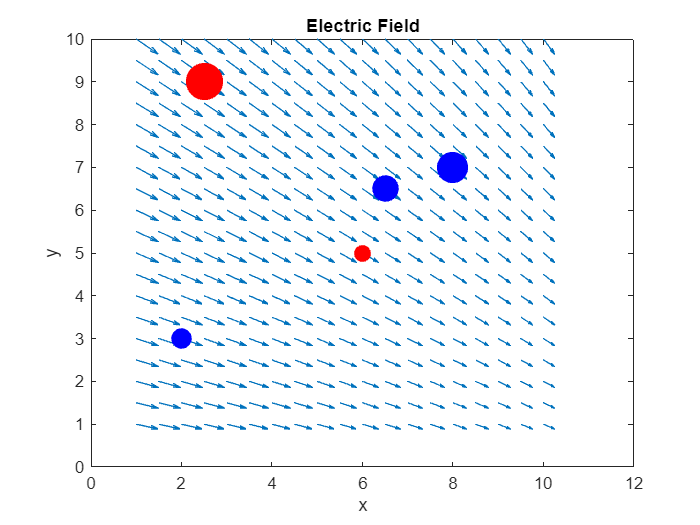

function [charge] = charge(x, y, q)
    % Charge function: returns [x, y, q] for a given charge.
    charge = [x, y, q];
end

function [chargesMatrix] = charges(varargin)
    % Charges function: takes in variable number of charge arrays
    % and appends them into a matrix.
    chargesMatrix = [];
    for i = 1:nargin
        chargesMatrix = [chargesMatrix; varargin{i}];
    end
end

function [] = eField(charges)
    [x_cord, y_cord] = meshgrid(1:0.5:10, 1:0.5:10);
    x_field = zeros(size(x_cord));
    y_field = zeros(size(y_cord));

    for x = 1:size(x_cord, 1)
        for y = 1:size(y_cord, 2)
            x_force = 0;
            y_force = 0;

            for i = 1:size(charges, 1)
                dx = x_cord(x, y) - charges(i, 1);
                dy = y_cord(x, y) - charges(i, 2);
                r = sqrt(dx^2 + dy^2);
                
                if r ~= 0
                    ex = charges(i, 3) * (dx / r^3);
                    ey = charges(i, 3) * (dy / r^3);
                    
                    x_force = x_force + ex;
                    y_force = y_force + ey;
                end
            end
            x_field(x, y) = x_force;
            y_field(x, y) = y_force;
        end
    end

    quiver(x_cord, y_cord, x_field, y_field);
    hold on;

    colors = zeros(size(charges, 1), 3);
    sizes = abs(charges(:, 3)) * 50;
    for i = 1:size(charges, 1)
        if charges(i, 3) < 0
            colors(i, :) = [0, 0, 1];
        else
            colors(i, :) = [1, 0, 0];
        end
    end

    scatter(charges(:, 1), charges(:, 2), sizes, colors, 'filled');
    title('Electric Field');
    xlabel('x');
    ylabel('y');
    hold off;
end

clf;
testCharges = charges(charge(2, 3, -3), charge(6, 5, 2), charge(6.5, 6.5, -5), charge(8, 7, -7), charge(2.5, 9, 10));
eField(testCharges);